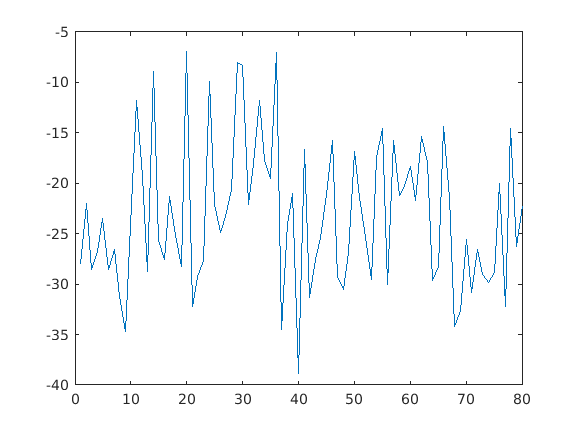

clear all
load RSS
plot(RSS)

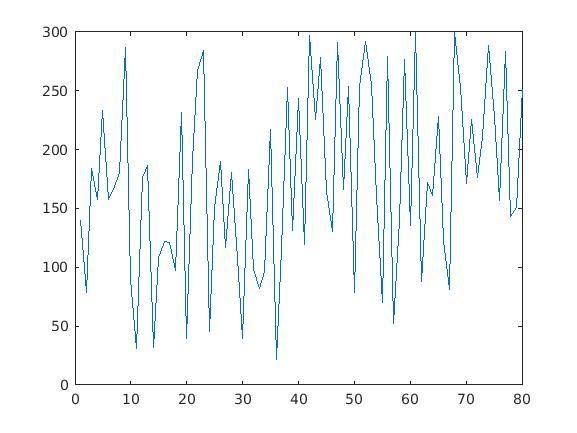

plot(d)

y = RSS';
d = d';


Part a

% model is RSS = 2*A + B/2*ln(d) + v_k
% vk ~N(0,5^2)
% [A;B] ~N([10;-20],20*I)

%this is linear fitting problem y = H*theta + epsilon_k,
% where 
% y = RSS
% H = [2,ln(d)/2]
% theta = [A;B]
% epsilon_k = v_k

%lets solve this problem, using model codes from exercise 2
H=[2*ones(size(d)) log(d)/2];
m0=[10;-20]; 
P0=20*eye(2); 
R=5^2*eye(80);

The posterior mean and covariance computed with the formulas of slide 2.11 are

K=P0*H'*inv(H*P0*H'+R);
mT=m0+K*(y-H*m0) 

mT =    11.1892
  -18.2031


PT=P0-K*H*P0

PT =     3.9228   -3.0833
   -3.0833    2.4725


%seems that posterior for
% A = 11.1892
% B = -18.2031

%Confidence interval 95%
%A
A_CI95 = [mT(1)-1.96*sqrt(PT(1,1)),mT(1)+1.96*sqrt(PT(1,1))]

A_CI95 =     7.3073   15.0712


%B
B_CI95 = [mT(2)-1.96*sqrt(PT(2,2)),mT(2)+1.96*sqrt(PT(2,2))]

B_CI95 =   -21.2851  -15.1212


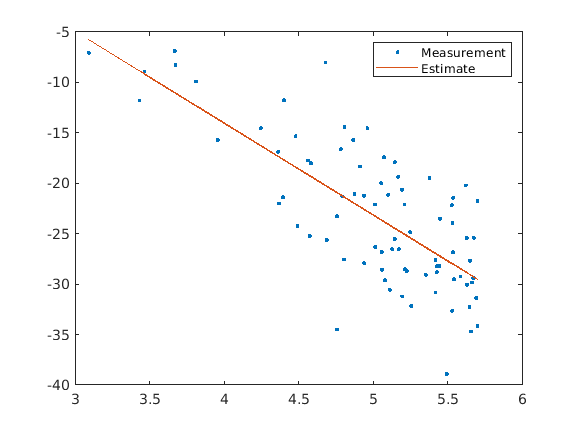


% plot to clarify if result is somehow correct
plot(log(d),y,'.',log(d),2*mT(1)+mT(2)*log(d)/2,'-');
legend('Measurement','Estimate');

Part b

%code taken from linreg_mcmc.m
% Gradient-free optimisation
logmvnpdf=@(x,m,P) -0.5*(x-m)'/P*(x-m)-trace(log(chol(2*pi*P)));
phiT=@(th) -logmvnpdf(y,H*th,R)-logmvnpdf(th,m0,P0);

% Robust Adaptive Metropolis algorithm
Sigma=eye(2)*0.002; 
Nburnin=1500; %CHANGED
N=15000;      %CHANGED
gamma=0.9; 
alpha_target=0.234;
theta=zeros(2,N);
accept_count=0;
theta_prev=mvnrnd(m0,P0)';
phi_prev=phiT(theta_prev);
S=chol(Sigma,'lower');
for i=1:N
    r=randn(size(m0));
    theta_prop=theta_prev+S*r;
    phi_prop=phiT(theta_prop);
    alpha=min(1,exp(phi_prev-phi_prop));
    if alpha>=rand
        accept_count=accept_count+1;
        theta(:,i)=theta_prop;
        theta_prev=theta_prop;
        phi_prev=phi_prop;
    else
        theta(:,i)=theta_prev;
    end
    if i>Nburnin
        eta=1/(i-Nburnin)^gamma;
        u=r/norm(r);
        SS=S*(eye(size(S))+eta*(alpha-alpha_target)*(u*u'))*S';
        S=chol(SS,'lower');
    end
end
disp('Robust Adaptive Random-walk Metropolis')

Robust Adaptive Random-walk Metropolis


mMCMC=mean(theta(:,Nburnin:end),2)

mMCMC =    10.7143
  -17.8269


Pmcmc=cov(theta(:,Nburnin:end)')

Pmcmc =     4.4798   -3.5173
   -3.5173    2.8098


accept_rate=accept_count/N

accept_rate = 0.6501

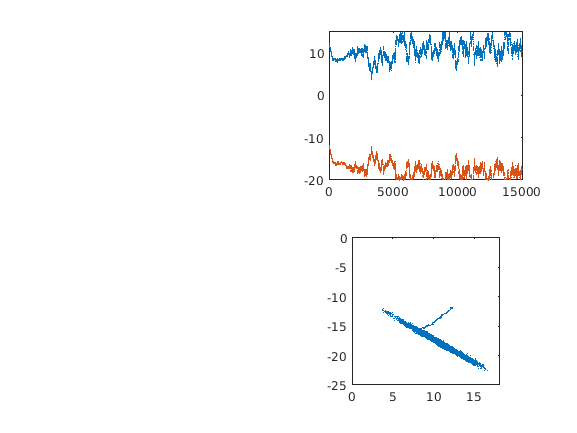

subplot(222)
plot(1:N,theta,'.','markersize',1)
axis([0 N -20 15]) %CHANGED
subplot(224)
plot(theta(1,:),theta(2,:),'.','markersize',1)
axis([0 18 -25 0]), axis square %CHANGED


%seems that posterior for
% A
A_MCMC = mMCMC(1)

A_MCMC = 10.7143

% B 
B_MCMC = mMCMC(2)

B_MCMC = -17.8269


%Confidence interval 95%
% A
A_MCMC_CI95 = quantile(theta(1,:),[0.025 0.975])

A_MCMC_CI95 =     6.4467   14.7246


% B
B_MCMC_CI95 = quantile(theta(2,:),[0.025 0.975])

B_MCMC_CI95 =   -20.9969  -14.1374
